# Opgave 4: Statisktik

En flødebolle-producent laver flødeboller, som skal veje 30.0 gram. 

Producenten får besøg af fødevarekontrollen, som tilfældigt udtager 12 flødeboller til kontrolvejning. 

De 12 flødeboller vejer: 

**a) Lav et Q-Q plot af målingerne. Er målingerne normalfordelte (svaret skal begrundes)? **

measurements=[1,2,3,4,5,6,7,8,9,10,11,12]

measurements =      1     2     3     4     5     6     7     8     9    10    11    12


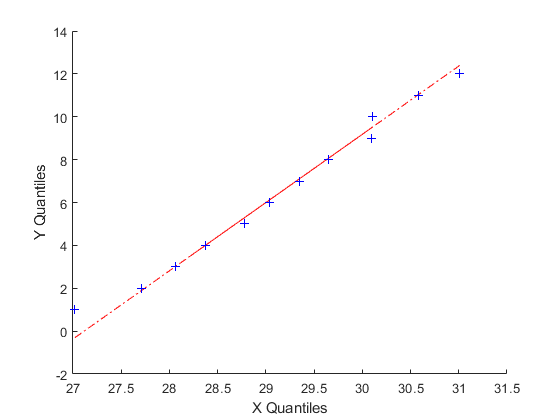

weights=[30.09,28.78,31.01,27.02,30.11,29.35,28.37,29.65,27.71,30.58,28.06,29.04];
qqplot(weights,measurements)

QQ-Plotet viser en ret linje og målingerne er derfor normalfordelt

**b) Hvilken test-statistik skal bruges til at teste om flødebollerne overholder den lovede vægt? **

 *I det at variansen er ukendt skal der bruges en ****student t-test***

**c) Opstil en nul-hypotese og en alternativ hypotese for testen. **

 H0: $\mu =\mu_0 =$ flødebolle vejer 30.0 gram

 H1: $\mu \not= \mu_0 =$ flødebolle vejer 30.0 gram

**d) Bestem sample middelværdi og sample varians af målingerne. **

sample_mean=(1/length(measurements))*sum(weights)

sample_mean = 29.1475

sample_variance=(1/(length(measurements)-1))*sum(power((weights-sample_mean),2))

sample_variance = 1.4687

*sample middelværdien er 29.1475*

*sample variansen er 1.469*

**e) Beregn p-værdien. Kan nul-hypotesen afvises med et signifikantniveau på 5%? **

test=(sample_mean-30)/(sqrt((sample_variance/length(measurements))))

test = -2.4368

p_value=2*(1-tcdf(abs(test),length(measurements)-1))

p_value = 0.0330

I det at pværdien ligger på 0.033, som er under 0.05, så kan nul-hypotesen afvises med et signifikantniveau på 5%.

H0 er afvist!

**f) Bestem 95% konfidensintervallet for flødebollernes vægt. Hvad fortæller det beregnede konfidensinterval? **

T0=tinv(0.975,length(measurements)-1)

T0 = 2.2010

step = T0*(sqrt((sample_variance/length(measurements))));
min= sample_mean-step

min = 28.3775

max= sample_mean+step

max = 29.9175

KonfidensInterval:[$\mu_{\mathrm{min}} ;\mu_{\mathrm{max}}$] = [28.377;29.918]

Konfidensintervallet fortæller os at flødbolle maskinen er konfigureret forkert og er indstillet til at lave for små flødeboller